# Pattern Classification - [tutorial](https://nl.mathworks.com/videos/image-recognition-using-machine-learning-122900.html)

## Data description

Our dataset consists of 4 objects: anchor, butterfly, cup and flamingo. The dataset was retrieved from the following link: [http://www.vision.caltech.edu/Image_Datasets/Caltech101/](http://www.vision.caltech.edu/Image_Datasets/Caltech101/) 

### Read images

imds = imageDatastore('images\task_1', "IncludeSubfolders",true,"LabelSource","foldernames");

### Display class names and counts

tbl = countEachLabel(imds)

tbl = 4×2 table
      Label      Count
    _________    _____

    anchor        42  
    butterfly     91  
    cup           57  
    flamingo      67  


categories = tbl.Label;

### Display sampling of image data

Here we select some 9 images from one of the image sets.

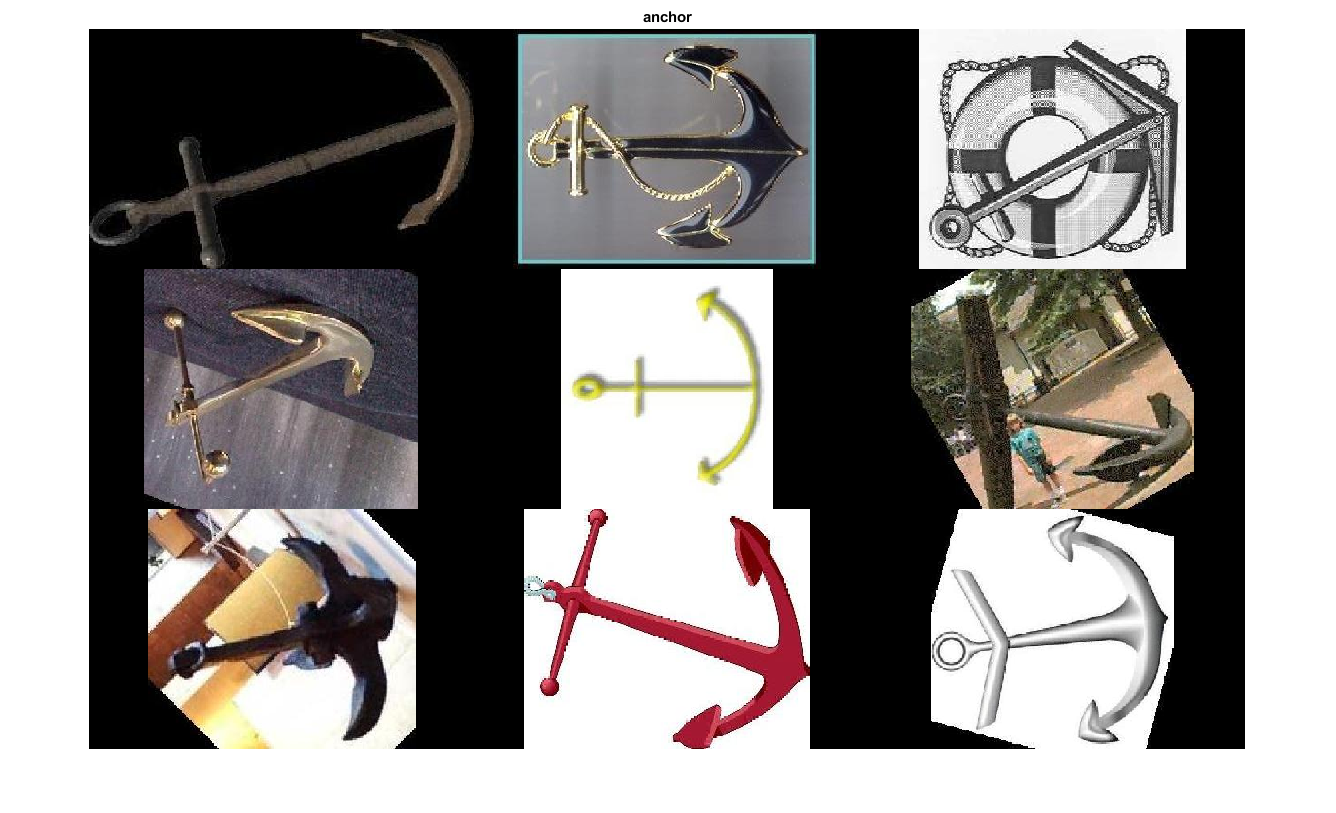

sample = splitEachLabel(imds,9);

montage(sample.Files(1:9));
title(char(tbl.Label(1)));

### Show sampling of all data

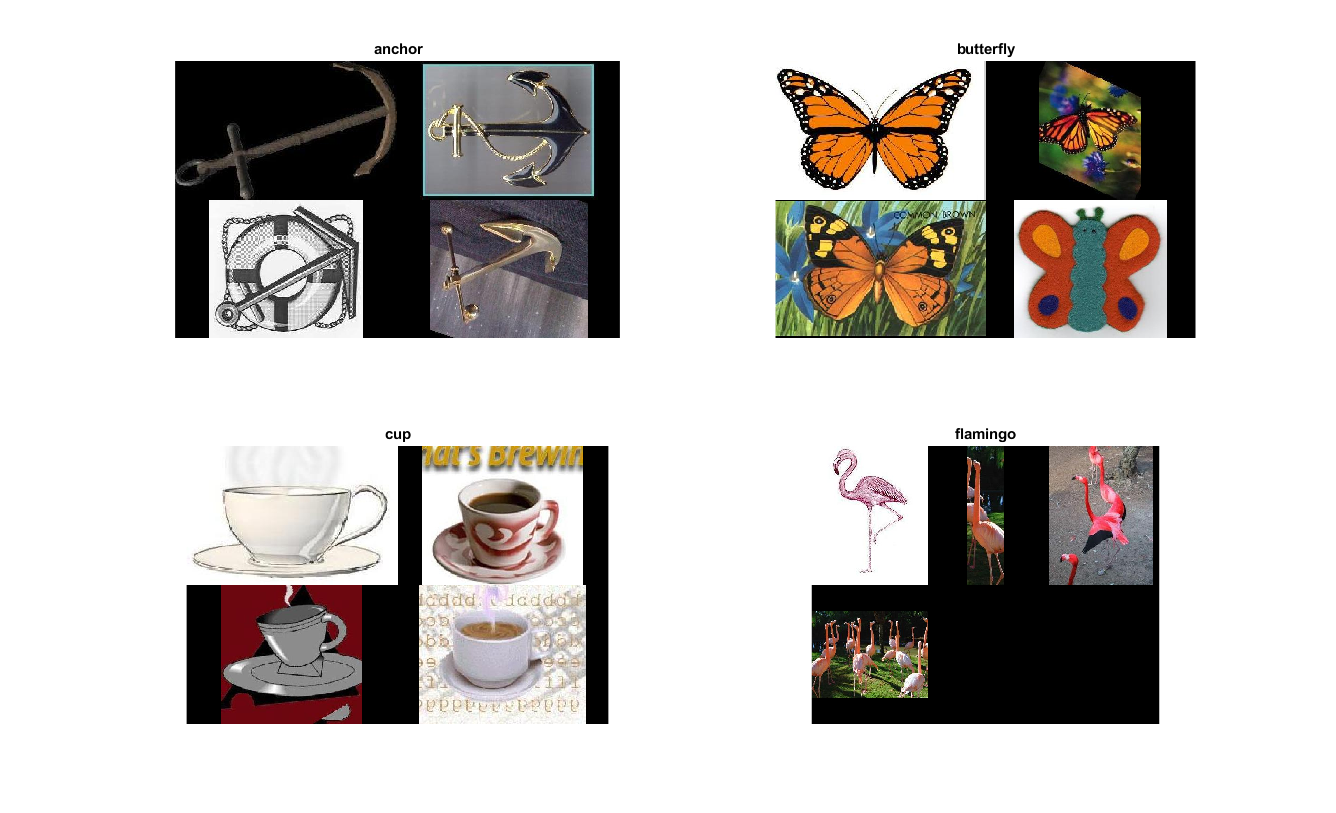

for i = 1:4
    sampleFiles = (i-1)*9 +1;
    ax(i) = subplot(2,2,i);
    montage(sample.Files(sampleFiles:sampleFiles+3));
    title(char(tbl.Label(i)));
end

## Pre-processing stage of the training data

### Feature extraction using "Bag of Features"

Bag of Features, also defined as Bag of Visual Words, is a way to extract features from images. In order to represent an image with this approach, an image can be treated as a document and occurance of visual "words" in images are used to generate a histogram that represents an image.

Basically, we count the number of times that we see some words, and based on their frequency we can describe those objects or scenes.

### Partition 30 images for training and 10 for testing

We do this partition by using a separate script.

[training_set, test_set] = prepareInputFiles(imds)

training_set =   1×4 imageSet array with properties:

    Description
    ImageLocation
    Count


test_set =   1×4 imageSet array with properties:

    Description
    ImageLocation
    Count


### Create Visual Vocabulary

tic
% Define the words
bag = bagOfFeatures(training_set,'VocabularySize',250,'PointSelection','Detector');

Creating Bag-Of-Features.
-------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Selecting feature point locations using the Detector method.
* Extracting SURF features from the selected feature point locations.
** detectSURFFeatures is used to detect key points for feature extraction.

* Extracting features from 30 images in image set 1...done. Extracted 7590 features.
* Extracting features from 30 images in image set 2...done. Extracted 6759 features.
* Extracting features from 30 images in image set 3...done. Extracted 4250 features.
* Extracting features from 30 images in image set 4...done. Extracted 5459 features.

* Keeping 80 percent of the strongest features from each category.

* Balancing the number of features across all image categories to improve clustering.
** Image category 3 has the l

% Count the occurences
scenedata = double(encode(bag, training_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Encoding 30 images from image set 1...done.
* Encoding 30 images from image set 2...done.
* Encoding 30 images from image set 3...done.
* Encoding 30 images from image set 4...done.

* Finished encoding images.



toc

Elapsed time is 4.979532 seconds.


### Visualize Feature vectors

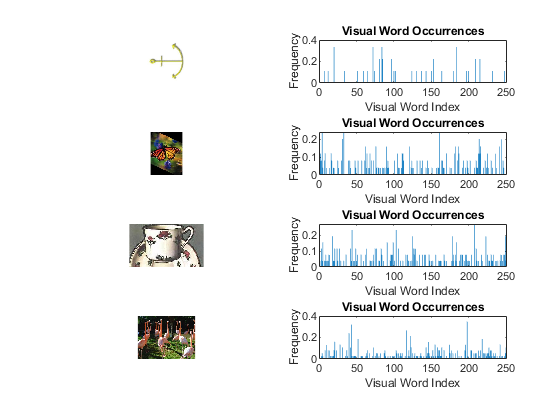

img = read(training_set(1), randi(training_set(1).Count));
featureVector = encode(bag, img);
figure;
subplot(4,2,1); imshow(img);
subplot(4,2,2); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = read(training_set(2), randi(training_set(2).Count));
featureVector = encode(bag, img);
subplot(4,2,3); imshow(img);
subplot(4,2,4);
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = read(training_set(3), randi(training_set(3).Count));
featureVector = encode(bag, img);
subplot(4,2,5); imshow(img);
subplot(4,2,6); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

img = read(training_set(4), randi(training_set(4).Count));
featureVector = encode(bag, img);
subplot(4,2,7); imshow(img);
subplot(4,2,8); 
bar(featureVector);title('Visual Word Occurrences');xlabel('Visual Word Index');ylabel('Frequency');

## Linear SVM ML Algorithm

In this section, we will use the Linear SVM classifier to train our model. 

This classifier was made using the Classification Learner app. This app helps the user train various models with the help of many machine learning algorithms such as SVMs (Support Vector Machines), KNNs (K Nearest Neighbor), and Neural Networks, among others.

Training our model with all the classifiers from the app, we determined that this classifier has the best validation accuracy, of 60.8%.

### Create table using the encoded features

Here we create a table that we are going to use for the classification learner in order to get the necessary results. 

The table features the image categories that we have selected from the data set.

SceneImageData = array2table(scenedata);
sceneType = categorical(repelem({training_set.Description}', [training_set.Count], 1));
SceneImageData.sceneType = sceneType;
correctTrainModel = linearSVMClassifier(SceneImageData);

### Determine the accuracy on the test image set

Here we calculate the accuracy of the classifier on the test images collected previously from our data set.

testSceneData = double(encode(bag, test_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Encoding 10 images from image set 1...done.
* Encoding 10 images from image set 2...done.
* Encoding 10 images from image set 3...done.
* Encoding 10 images from image set 4...done.

* Finished encoding images.



testSceneData = array2table(testSceneData,'VariableNames',correctTrainModel.RequiredVariables);
actualSceneType = categorical(repelem({test_set.Description}', [test_set.Count], 1));

predictedOutcome = correctTrainModel.predictFcn(testSceneData);

correctPredictions = (predictedOutcome == actualSceneType);
validationAccuracy = sum(correctPredictions)/length(predictedOutcome)

validationAccuracy = 0.2750

### Visualizing the classifier

i = randi(size(test_set,2));
j = randi(test_set(i).Count);
img = read(test_set(i),j);

figure;
imshow(img);

We now invoke the trained classifier:

imagefeatures = double(encode(bag, img));

Then find two closest matches for each feature

[bestGuess, score] = predict(correctTrainModel.ClassificationSVM,imagefeatures);

Display the result as a label to the image. A green label signifies a correct prediction, while a red label means an incorrect prediction from the classifier.

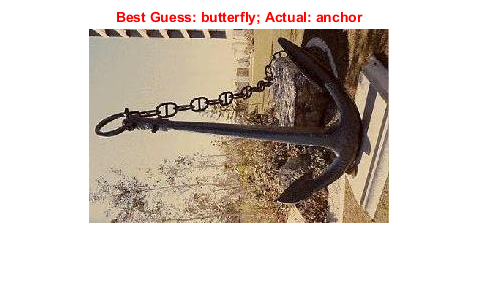

if strcmp(char(bestGuess),test_set(i).Description)
	titleColor = 'g';
else
	titleColor = 'r';
end
title(sprintf('Best Guess: %s; Actual: %s',...
	char(bestGuess),test_set(i).Description),...
	'color',titleColor)

## Narrow Neural Network ML Algorithm

This section of the live script makes use of another machine learning algorithm, the Narrow Neural Network classifier. It follows the same flow as the previous classifier. 

This one, together with the Linear SVM classifier, have the highest accuracy among others, although slightly lower at 59.2%

correctTrainModel2 = narrowNeuralNetworkClassifier(SceneImageData);

testSceneData2 = double(encode(bag, test_set));

Encoding images using Bag-Of-Features.
--------------------------------------
* Image category 1: anchor
* Image category 2: butterfly
* Image category 3: cup
* Image category 4: flamingo
* Encoding 10 images from image set 1...done.
* Encoding 10 images from image set 2...done.
* Encoding 10 images from image set 3...done.
* Encoding 10 images from image set 4...done.

* Finished encoding images.



testSceneData2 = array2table(testSceneData2,'VariableNames',correctTrainModel2.RequiredVariables);
actualSceneType2 = categorical(repelem({test_set.Description}', [test_set.Count], 1));
predictedOutcome2 = correctTrainModel2.predictFcn(testSceneData2);
correctPredictions = (predictedOutcome2 == actualSceneType2);
validationAccuracy = sum(correctPredictions)/length(predictedOutcome2) %#ok

validationAccuracy = 0.3500

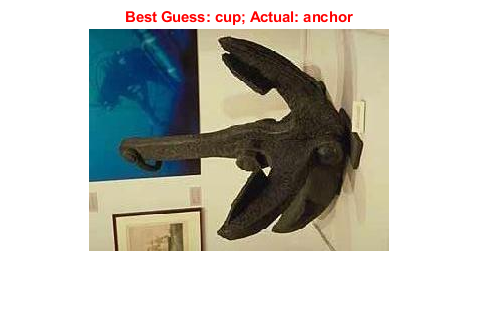


i = randi(size(test_set,2));
j = randi(test_set(i).Count);
img = read(test_set(i),j);

figure;
imshow(img);

imagefeatures = double(encode(bag, img));

[bestGuess, score] = predict(correctTrainModel2.ClassificationNeuralNetwork,imagefeatures);

if strcmp(char(bestGuess),test_set(i).Description)
	titleColor = 'g';
else
	titleColor = 'r';
end
title(sprintf('Best Guess: %s; Actual: %s',...
	char(bestGuess),test_set(i).Description),...
	'color',titleColor)

## Questions

**Explain the new feature extraction technique you used. Does it outperform the bag of features?**

Unfortunately, due to time constraints, we have not been able to use another feature extraction method, only managing to use the "Bag of Features".

**Document the steps you took to train, validate, fine tune and test the model.**

These steps are featured throughout the live script.

**Compare the performance of the two ML algorithms you tried. What is the success rate of your classification? **

The two ML algorithms used in this live script are the Linear SVM and Narrow Neural Network. These proved to have the highest accuracy in comparison to all the others, with 60.8% and 59.2% accuracy respectively.

**Analyse when and why misclassification occurs.**

Misclassification is dependent on the accuracy of the machine learning algorithm. As the accuracy is lower, the error rate becomes higher. These occur once a model is trained, and can be observed with the help of a confusion matrix, which show the predictions made by the classifier. The accuracy is then determined by calculating the division of correct predictions, from the total possible cases. The lower the incorrect predictions, the better!

## **Reflection**

**What was the most difficult part? **

I believe the most difficult part of this task was understanding how to use the Classification Learner app. Previously, I missed an important part from the script, creating a new table with the encoded features, which led to an erroneous training model, and resulted in alot of confusion. After figuring out the mistake on my part, I managed to get the desired results from the app.

**Do you have suggestions for improvement? **

I would have liked to be able to try out other feature extraction techniques. The "Bag of Features" technique proved to be useful enough, but it would have been interesting to see how other methods fared.